# Aula 3 - Laboratório de Controle - 2021/1 

## Identificação de modelos a partir de dados

## Nome: Yuri Rissi Negri

**Atividade 1: Análise da resposta do motor**

O modelo do motor utiizado é mostrado na Figura 1. A entrada é o sinal PWM e a saída agora é a rotação, em RPM. Um sinal de ruído é adicionado a saída.

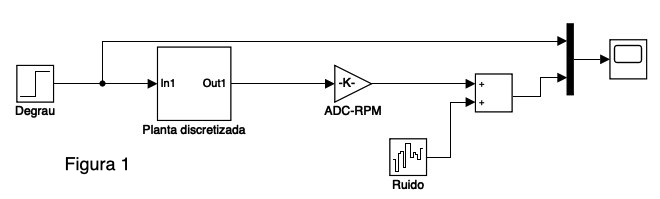

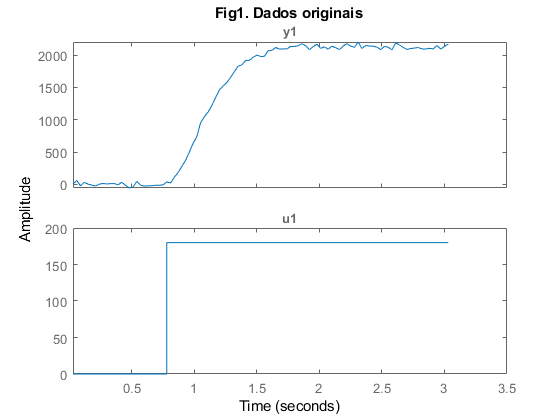

Tempo = 3;
arquivo='aula3_2018.slx';
Stepdelay=0.25*Tempo;

[wn,PWM,rpm_r,Ts]=init(8,5);
warning('off','all');
[y,u,t]=simula_slx(arquivo,Tempo);
dat=iddata(y,u,Ts);
plot(dat); title('Fig1. Dados originais')

1.1 Explicar o que representam as duas curvas da Figura 1.

    A primeira curva representa a nossa saída para o modelo do motor. Essa que será a rotação do motor somado de um ruido que foi introduzido ao sistema. O ruido dificulta na nossa analise, mas podemos dizer que em regime permanente, nosso primeiro gráfico apresenta um valor aproximado de Y = 2100.

    Já o nosso segundo gráfico, é referente a nossa entrada em PWM, que está relacionada ao numero de rotações do motor, e em regime permanente em Y= 180 para os parâmetros adotados. Podemos observar também que o atraso das duas curvas são próximas está em torno de 0,75 segundos.

1.2 Calcular o valor da entrada PWM para ter em regime uma saída de velocidade = rpm_r. Explicar o cálculo e informar como obter o valor da saída em regime na figura 2. 

    Nossa entrada PWM esta relacionada a nossa saída pelo ganho do sistema, que é dado por K = (saída/entrada) em regime permanente. Do item anterior podemos então calcular o ganho aproximado para esse sistema:

K = 2100/180 = 11,67

    Assim, para uma valor de rpm_r = 2000, podemos isolar a entrada na formula do ganho, e utilizando o K calculado, encontrar a entrada PWM para gerar essa saída.

entrada = (saída/K) = 2000/11,67 ~= 171

PWM =171

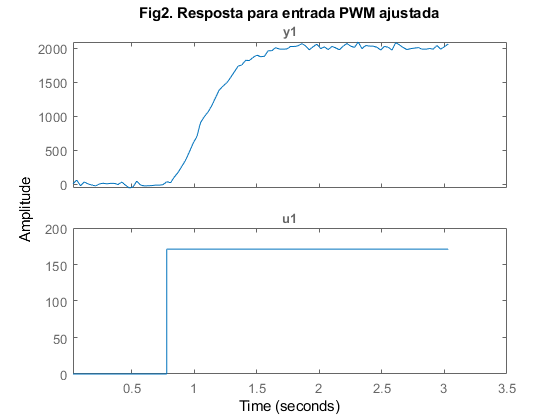

PWM=171;
[y,u,t]=simula_slx(arquivo,Tempo);
dat=iddata(y,u,Ts);
plot(dat);title('Fig2. Resposta para entrada PWM ajustada')

**Atividade 2: Identificação dos modelos contínuos de ordem 1 e 2**

Ler o apêndice sobre a identificação de funções de transferência e o sobre o índice fit para medir a qualidade do modelo. Depois, use os comandos abaixo para estimar a FT g1 de ordem 1 e a FT g2 de ordem 2.

delay=t(sum(y<0.1*y(end)))-Stepdelay;
g1=tfest(dat,1,0,delay)


g1 =
 
  From input "u1" to output "y1":
                   41.79
  exp(-0.09*s) * ---------
                 s + 3.483
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "dat".
Fit to estimation data: 94.24%                  
FPE: 2779, MSE: 2619                            


g2=tfest(dat,2,0) 


g2 =
 
  From input "u1" to output "y1":
          295.5
  ---------------------
  s^2 + 8.612 s + 25.06
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "dat".
Fit to estimation data: 96.98%                  
FPE: 795.1, MSE: 720.1                          


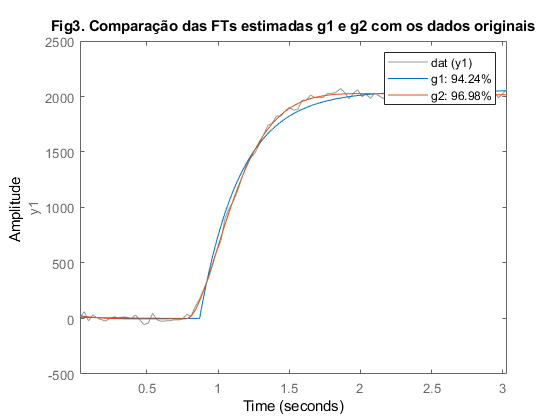


figure;compare(dat,g1,g2);
title('Fig3. Comparação das FTs estimadas g1 e g2 com os dados originais');

2.1 Explique o comando tfest e analise o FIT de g1 e g2, comparando.

     O comando tfest estima uma função de transferência com parâmetros especificados, no caso o número de pólos e zeros, que se aproxima da curva original, no nosso caso, dada por "dat". Assim, podemos gerar uma curva de aproximação com ordem desejada, a fim de se obter o melhor resultado, onde a qualidade da aproximação é dado pelo calculo da métrica FIT. Assim analisando o gráfico da figura 3, podemos perceber que a curva g2 apresenta um FIT mais próximo de 100% em comparação a curva g1, ou seja, a curva g2 apresenta um erro menor sobre a saída quando comparada a g1, sendo uma melhor aproximação. Isso se dá pelo fato que foi estimado uma FT de ordem maior para g2, o que diminui o erro, mas também aumenta a dificuldade de análise por apresentar mais pólos.

2.2 Compare esse método de estimar g1 ao utilizado na aula 2 (atividade 2).

    Durante a aula 2, para podermos estimar a nossa curva tivemos que encontrar manualmente o ganho, a constante de tempo e o atraso da nossa curva original a fim de traçar varias curvas, fixando o ganho, mas com diferentes valores de atraso. Dessa forma, selecionar a curva que apresentou um menor erro dentre nossa faixa de valores, e a constante de tempo associado.

    Em comparação, o método que utilizamos para estimar g1, utiliza amostras da nossa função original "dat" como parâmetro de entrada para a função tfest, juntamente com o número de pólos e zeros. Também é dado como entrada o atraso de tempo delay, calculado pela função delay=t(sum(y<0.1*y(end)))-Stepdelay.

    Assim a função estima a FT que nos gera melhor curva para aquela ordem de sistema,  juntamente com o índice FIT sem a necessidade de se calcular o ganho e testar diferentes atrasos de tempo e constantes de tempo. Dessa forma, o método desta aula utilizou muito menos etapas e linhas de código, sendo assim mais prático.

2.3 Compare g1 com a FT G de primeira ordem+tempo morto $G=\frac{e^{ds}K}{\tau s + 1}$ e obtenha o ganho $K$ e a constante de tempo $\tau$.

    Para obter o ganho e a constante de tempo, devemos antes manipular a FT de g1 para que a mesma fique como em $G=\frac{e^{ds}K}{\tau s + 1}$ 

    Assim, para o nosso caso, basta dividir o denominador e numerador por 3,483. Vamos obter assim:

$K$ = 41,79/3,483 = 12

$\tau$ = 1/3,483 = 0,287 s

2.4  Compare g2 com o protótipo de segunda ordem em malha fechada $M(s)=\frac{w_n^2}{s^2+2\zeta w_n s + wn^2}$ e obtenha $\zeta$ e $w_n$. 

    O enunciado nos pede para encontrar os elementos associados a malha fechada, assim, utilizando o comando para obter g2 em malha fechada: 

g2f = feedback (g2, 1)


g2f =
 
  From input "u1" to output "y1":
          295.5
  ---------------------
  s^2 + 8.612 s + 320.6
 
Continuous-time transfer function.



[Wn,zeta] = damp(g2f)

Wn =    17.9052
   17.9052


zeta =     0.2405
    0.2405


**Atividade 3 - Aproximação de Padé do tempo morto**

A aproximação de [Padé](https://youtu.be/zDRTsU2DZSk) permite aproximar o atraso $e^{-ds}$ por polos e zeros, e assim obter FTs racionais na presença de atrasos (ver apêndice 2)

No script a seguir, usa-se aproximação de Padé de ordem 1,2,10 para aproximar o tempo morto de g1 por polinômios.

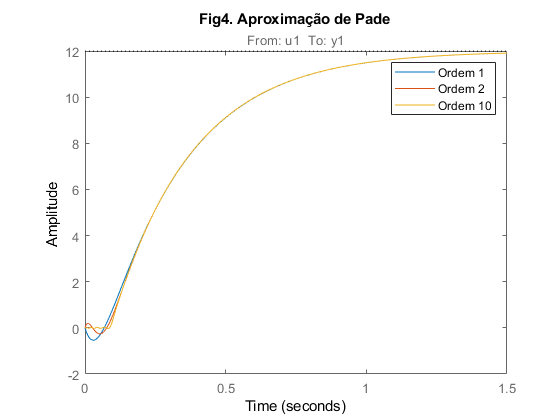

g1p=pade(g1,1);
g2p=pade(g1,2);
g10p=pade(g1,10);
figure(7);step(g1p , g2p, g10p, Tempo/2 );title('Fig4. Aproximação de Pade');legend('Ordem 1', 'Ordem 2', 'Ordem 10');

3.1 Use a aproximação de Padé para obter uma FT de malha fechada m1 de g1 e obtenha seus polos (ver links de ajuda na aula 2).

    Vamos utilizar a g1 por ser de menor ordem, para facilitar a análise. Sendo assim, temos g1p a aproximação de Padé para g1, utilizou se os comandos para encontrar a FT em malha fechada e os pólos da mesma: 

m1 = feedback (g1p, 1)


m1 =
 
  From input "u1" to output "y1":
    -41.79 s + 928.6
  --------------------
  s^2 - 16.08 s + 1006
 
Continuous-time transfer function.



pole (m1)

ans =    8.0413 +30.6818i
   8.0413 -30.6818i


3.2 Use o comando [rlocus](https://www.mathworks.com/help/control/ref/tf.rlocus.html) para explicar o que ocorre com as raízes de 1+kg1(s)=0 (polos de malha fechada) quando o ganho k varia de zero a infinito (coloque apenas texto e informações do LR, sem comandos ou figuras).

    Como explicado anteriormente vamos tomar a função g1p, por ser a de menor ordem, terá um menor numero de pólos, o que facilitara a nossa análise. Para g1p, iremos ter 2 pólos e um zero. Utilizando o comando rlocus, o mesmo irá automaticamente fechar a malha e tomar os pólos e zeros de malha aberta, e traçar assim os caminhos para todos os valores de raízes possíveis.

    Assim, analisando o gráfico, vamos ter dois pólos onde K = 0:

    Pólos de malha aberta: (-22,2 ; -3,5)

    E vamos ter um zero onde K = infinito:

    Zero: (22,2)

    Portanto, vamos ter dois caminhos em que K vai de 0 a infinito. Sabemos também, que para o tempo continuo, para atender o critério de estabilidade, nossa raiz deve se encontrar do lado esquerdo do nosso eixo imaginário. Como nossos dois caminhos tendem para o lado direito do eixo imaginário, vamos ter um K limite que atenda a estabilidade. Esse K será dado quando o caminho interceptar o eixo imaginário. Sendo assim tomando o ponto graficamente, vamos ter:

Klim = 0,61 em +25,4i e -25,4i , que são os pontos onde os caminhos interceptam o eixo.

Assim, para valores menores que Klim o sistema será estável, enquanto que para qualquer valor maior que nosso Klim, vamos ter um sistema instável. 

datetime('now')

ans = datetime
   02-Jul-2021 21:08:00


pwd

ans = 'C:\Users\asus1\Desktop\Aula 3'

**Apêndice 1**

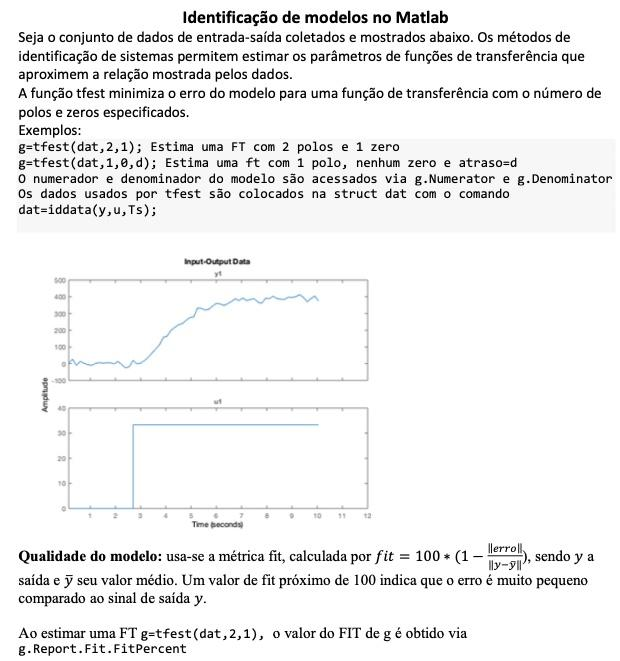

**Apêndice 2**